# Driving LEDs 

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

clear all
Vin(:,1)=0:0.0001:1; %time;
Vin(:,2)=0:0.0001*5:5;
model_name = 'LEDControl';
open_system(model_name)
% Set Simulation Mode the parameter in PWM to "Average"
set_param('LEDControl/PWM','pwm_or_av','2');
%m = sdo.getParameterFromModel(model_name, 'PWM');
simOut = sim(model_name, 'CaptureErrors', 'on');

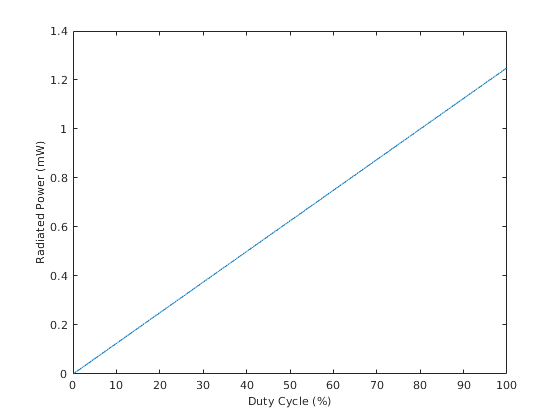

figure
plot(simOut.voltage_in.Data*100/5,simOut.Power_out.Data*1000)
xlabel('Duty Cycle (%)', 'FontSize', 10)
ylabel('Radiated Power (mW)', 'FontSize', 10)

figure



clear all
Vin(:,1)=0:0.0001:1; %time;
Vin(:,2)=2;
model_name = 'LEDControl';
% Set Simulation Mode the parameter in PWM to "PWM"
set_param('LEDControl/PWM','pwm_or_av','1'); 
simOut = sim(model_name, 'CaptureErrors', 'on');

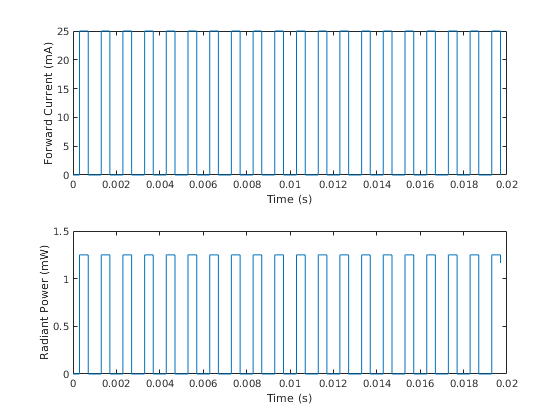

figure
subplot(211),
plot(simOut.current_out.Time(1:2000), simOut.current_out.Data(1:2000)*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Forward Current (mA)', 'FontSize', 10)
subplot(212),
plot(simOut.current_out.Time(1:2000), simOut.Power_out.Data(1:2000)*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Radiant Power (mW)', 'FontSize', 10)

% plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)
% xlabel(' Reverse Voltage (V)', 'FontSize', 10)
% ylabel('Reverse Light Current (µA)', 'FontSize', 10)
% 
% 
% clear all
% Irr1(:,1)=0:0.01:10; %time
% Irr1(:,2)=10; % irradiance
% Vin(:,1)=0:0.01:10; %time;
% Vin(:,2)=-5:0.01:5;
% simOut = sim('photodiode', 'CaptureErrors', 'on');
% hold on
% plot(-simOut.diode_out.Data,-simOut.current_out.Data*1e6)